# One-Dimensional Gaussian Process

## Create joint prior of the training and test points

% assign training points (tSTARi, fSTARi)
Npoints = 100;
MINt = 0; MAXt = 20;

t = sortrows( ( MINt + (MAXt-MINt) .* rand(1,Npoints) )' );
f = exp(rand * t) + rand(1,Npoints)';

## Fit the GP using the matlab built in function

%
KernelType = 'SquaredExponential';
Sigma0 = 1; kparams0 = [1 1];
GPmodel = fitrgp(t,f,'KernelFunction',KernelType,'KernelParameters',kparams0,'Sigma',Sigma0);

% predict for some values of tstar
tstar = (MINt : 0.01 : MAXt )';
[fstarAVG, ~, fstar95] = predict(GPmodel, tstar); % media e intervalli di confidenza

loo = crossval(GPmodel)

loo =   classreg.learning.partition.RegressionPartitionedModel
    CrossValidatedModel: 'GP'
         PredictorNames: {'x1'}
           ResponseName: 'Y'
        NumObservations: 100
                  KFold: 10
              Partition: [1×1 cvpartition]
      ResponseTransform: 'none'


  Properties, Methods


## Plot

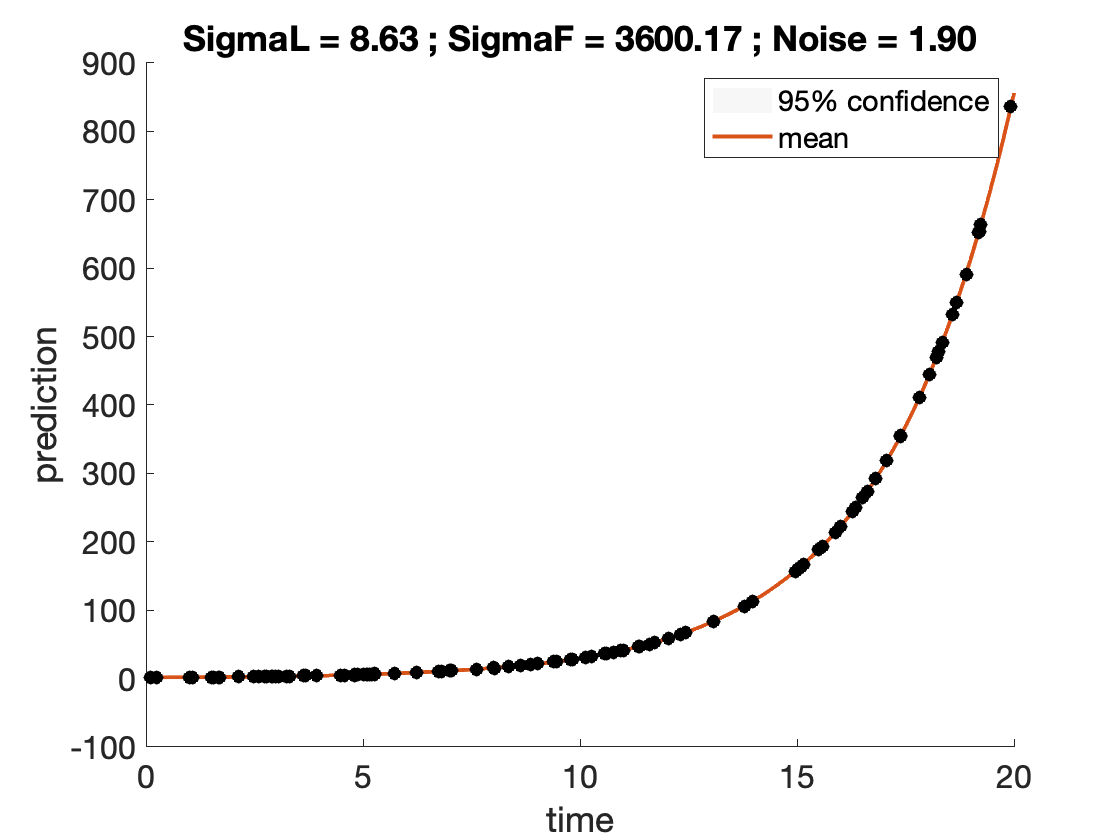

figure
hold on

area=fill([tstar; flipud(tstar)], [fstar95(:,1); flipud(fstar95(:,2))], [.97 .97 .97]); set(area,'Edgecolor','w')
plot(tstar, fstarAVG, 'Linewidth', 2)
plot(t, f, 'ok', 'MarkerFaceColor','k')
legend('95% confidence', 'mean')

title(sprintf('%s = %2.2f ; %s = %2.2f ; Noise = %2.2f', GPmodel.KernelInformation.KernelParameterNames{1}, GPmodel.KernelInformation.KernelParameters(1), GPmodel.KernelInformation.KernelParameterNames{2}, GPmodel.KernelInformation.KernelParameters(2), GPmodel.Sigma))
xlabel('time'); ylabel('prediction')
set(gca, 'Fontsize', 16)


figure
bar(1:Npoints, loo)

Error using bar (line 127)
Input arguments must be numeric, datetime, duration or categorical.